planes = planeData(2:end,:);
Fpatterson = F(2:end);

points = 50;

position = ones([1 points]).*linspace(0,1,points);
P = zeros([points points points]);

for u = 1:points
    for v = 1:points
        for w = 1:points
            for plane = 1:length(planes)
                h = planes(plane,1);
                k = planes(plane,2);
                l = planes(plane,3);
                
                P(u,v,w) = P(u,v,w) + ...
                    ((abs(Fpatterson(plane)))^2)*...
                    exp(-1i*2*pi*(h*position(u)+k*position(v)+l*position(w)));
            end
        end
    end
end

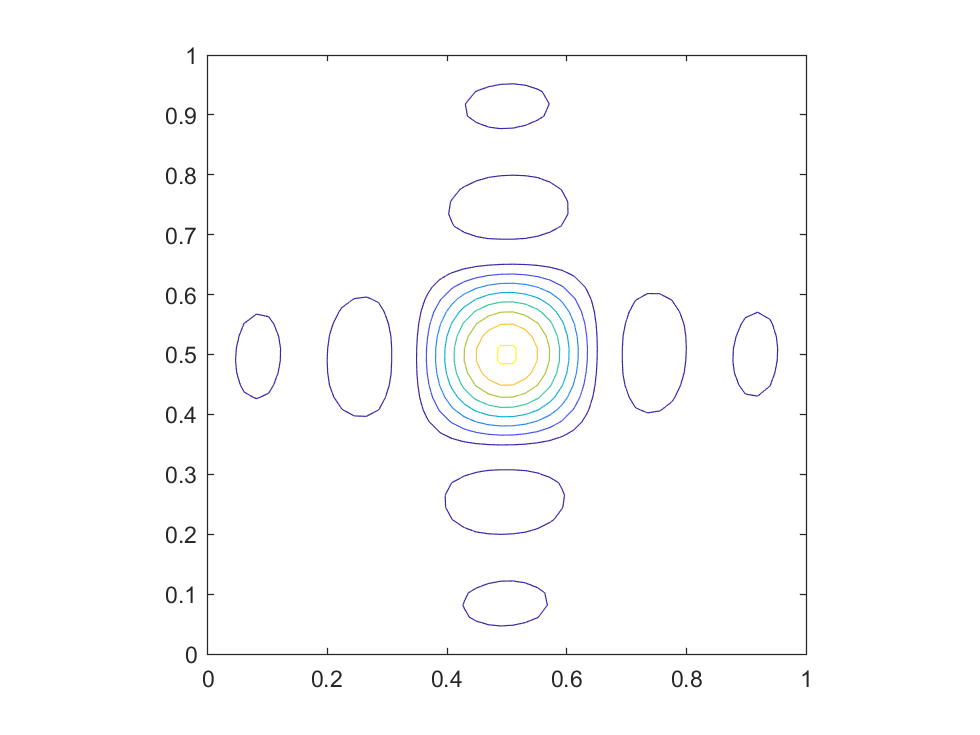

contour(position,position,abs(P(:,:,25)))
axis equal